Dataset tomado de

[https://es.investing.com/indices/us-spx-500-historical-data](https://es.investing.com/indices/us-spx-500-historical-data)

clear,
close all,
clc,
rng(5);

Lo primero que se hará es cargar el dataset con el histórico de fechas desde el 2000 hasta hoy del SP500

load("dataset.mat");
DatoshistoricosSP500 = flipud(DatoshistoricosSP500);
orden_predictor =5;

El orden del predictor lo que hará es decir cuantos lags tendrá el dataset y también nos dará el número de neuronas de entrada, para generar el dataset lo que se hará es generar muestras retardadas para cada columna

dataset = zeros(length(DatoshistoricosSP500.Ultimo),orden_predictor+1);
dataset(:,end) = DatoshistoricosSP500.Ultimo;
for i=1:1:orden_predictor
    dataset(i+1:end,end-i) = dataset(1:end-i,end);
end

Después de esto se definirá el número de neuronas y número de capas

num_neuronas = 5;
num_capas = 5;
net_config = num_neuronas.*ones(1,num_capas);


Como paso siguiente se le hará shuffle al dataset para poder obtener los resultados sin sesgo

shuffled_dataset = shuffle_dataset(dataset);

Ahora lo que se procederá a hacer es el split del dataset para tener para hacer train, test y validation, para efectos de validación en la visualización se repartirán sin hacer shuffle y haciendo shuffle

porcentaje_test = 0.2;
porcentaje_validacion = 0.1;
[X_train,Y_train,X_test,Y_test,X_val,Y_val] = split_dataset(porcentaje_test,porcentaje_validacion,dataset);
[X_train_shuffled,Y_train_shuffled,X_test_shuffled,Y_test_shuffled,X_val_shuffled,Y_val_shuffled] = split_dataset(porcentaje_test,porcentaje_validacion,shuffled_dataset);

Se configura la red

net = feedforwardnet(net_config);
%Configuraciones de la red
%Usamos todo el dataset provisto a la red para entrenar dado que los de
%validación y test los tenemos en otras variables y matlab no permite
%proveerlos a través de este toolbox
net.divideParam.trainRatio = 1;
net.divideParam.valRatio = 0;
net.divideParam.testRatio = 0;
%Configuraciones de las capas
% Coloque en la consola help nntransfer para ver las funciones que hay
funcion_capas_ocultas = "tansig";
for i = 1:1:num_capas
    net.layers{i}.transferFcn = funcion_capas_ocultas;
end
%LA ULTIMA CAPA SIEMPRE ES LA DE SALIDA
net.layers{num_capas+1}.transferFcn = "purelin";
%FIN Configuraciones de la red

Y finalmente se procede a entrenar con los datos shuffled

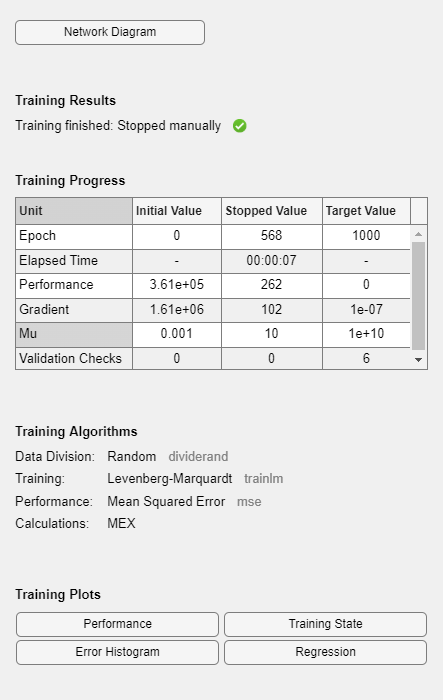

[net,errTrain,errVal,errTest] = entrenar(net,X_train_shuffled,Y_train_shuffled,X_test_shuffled,Y_test_shuffled,X_val_shuffled,Y_val_shuffled);

Visualizamos los datos reales vs los obtenidos

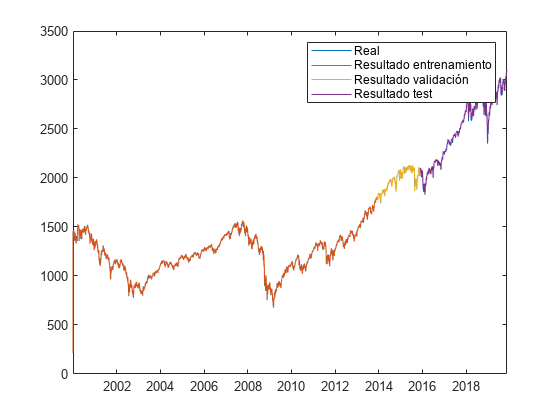

[filas, columnas] = size(dataset);
Fechas_train = DatoshistoricosSP500.Fecha(1:round(filas*(1-porcentaje_validacion-porcentaje_test)));
Fechas_test = DatoshistoricosSP500.Fecha(round(filas*(1-porcentaje_validacion-porcentaje_test))-1:round(filas*(1-porcentaje_test)));
Fechas_val = DatoshistoricosSP500.Fecha(round(filas*(1-porcentaje_test))-1:end);
figure,
plot(DatoshistoricosSP500.Fecha, DatoshistoricosSP500.Ultimo);
hold on;
Y_train_pred = sim(net,X_train');
plot(Fechas_train,Y_train_pred);
Y_test_pred = sim(net,X_test');
plot(Fechas_test,Y_test_pred);
Y_val_pred = sim(net,X_val');
plot(Fechas_val,Y_val_pred);
legend("Real","Resultado entrenamiento","Resultado validación","Resultado test");